# Exercise 1 : Déclaration de variable

Vmax = 400; %en km\h
Vmax = Vmax * 1000 / 3600; % en m/s
g = 9.81; % Force gravitationelle de la terre
Amax = 5.88; %en m/s2

## Exercise 1: Formules

t0 = 0;
t1 = 18.87;
t2 = 90.01;
t3 = 108.83;

A1 = Amax;
A2 = 0;
A3 = -Amax;

V1 = @(t) Amax * t;
V2 = Vmax;
V3 = @(t) -Amax*(t-t2) + (Amax*t1);

D1 = @(t) Amax/2 * t.^2;
D2 = @(t) (Vmax * (t-t1)) + (Amax/2 * t1.^2);
D3 = @(t) (-Amax/2 * (t-t2).^2) + (Vmax * (t-t1)) + (Amax/2 * t1.^2) ;


## Exercise 1: Graphiques

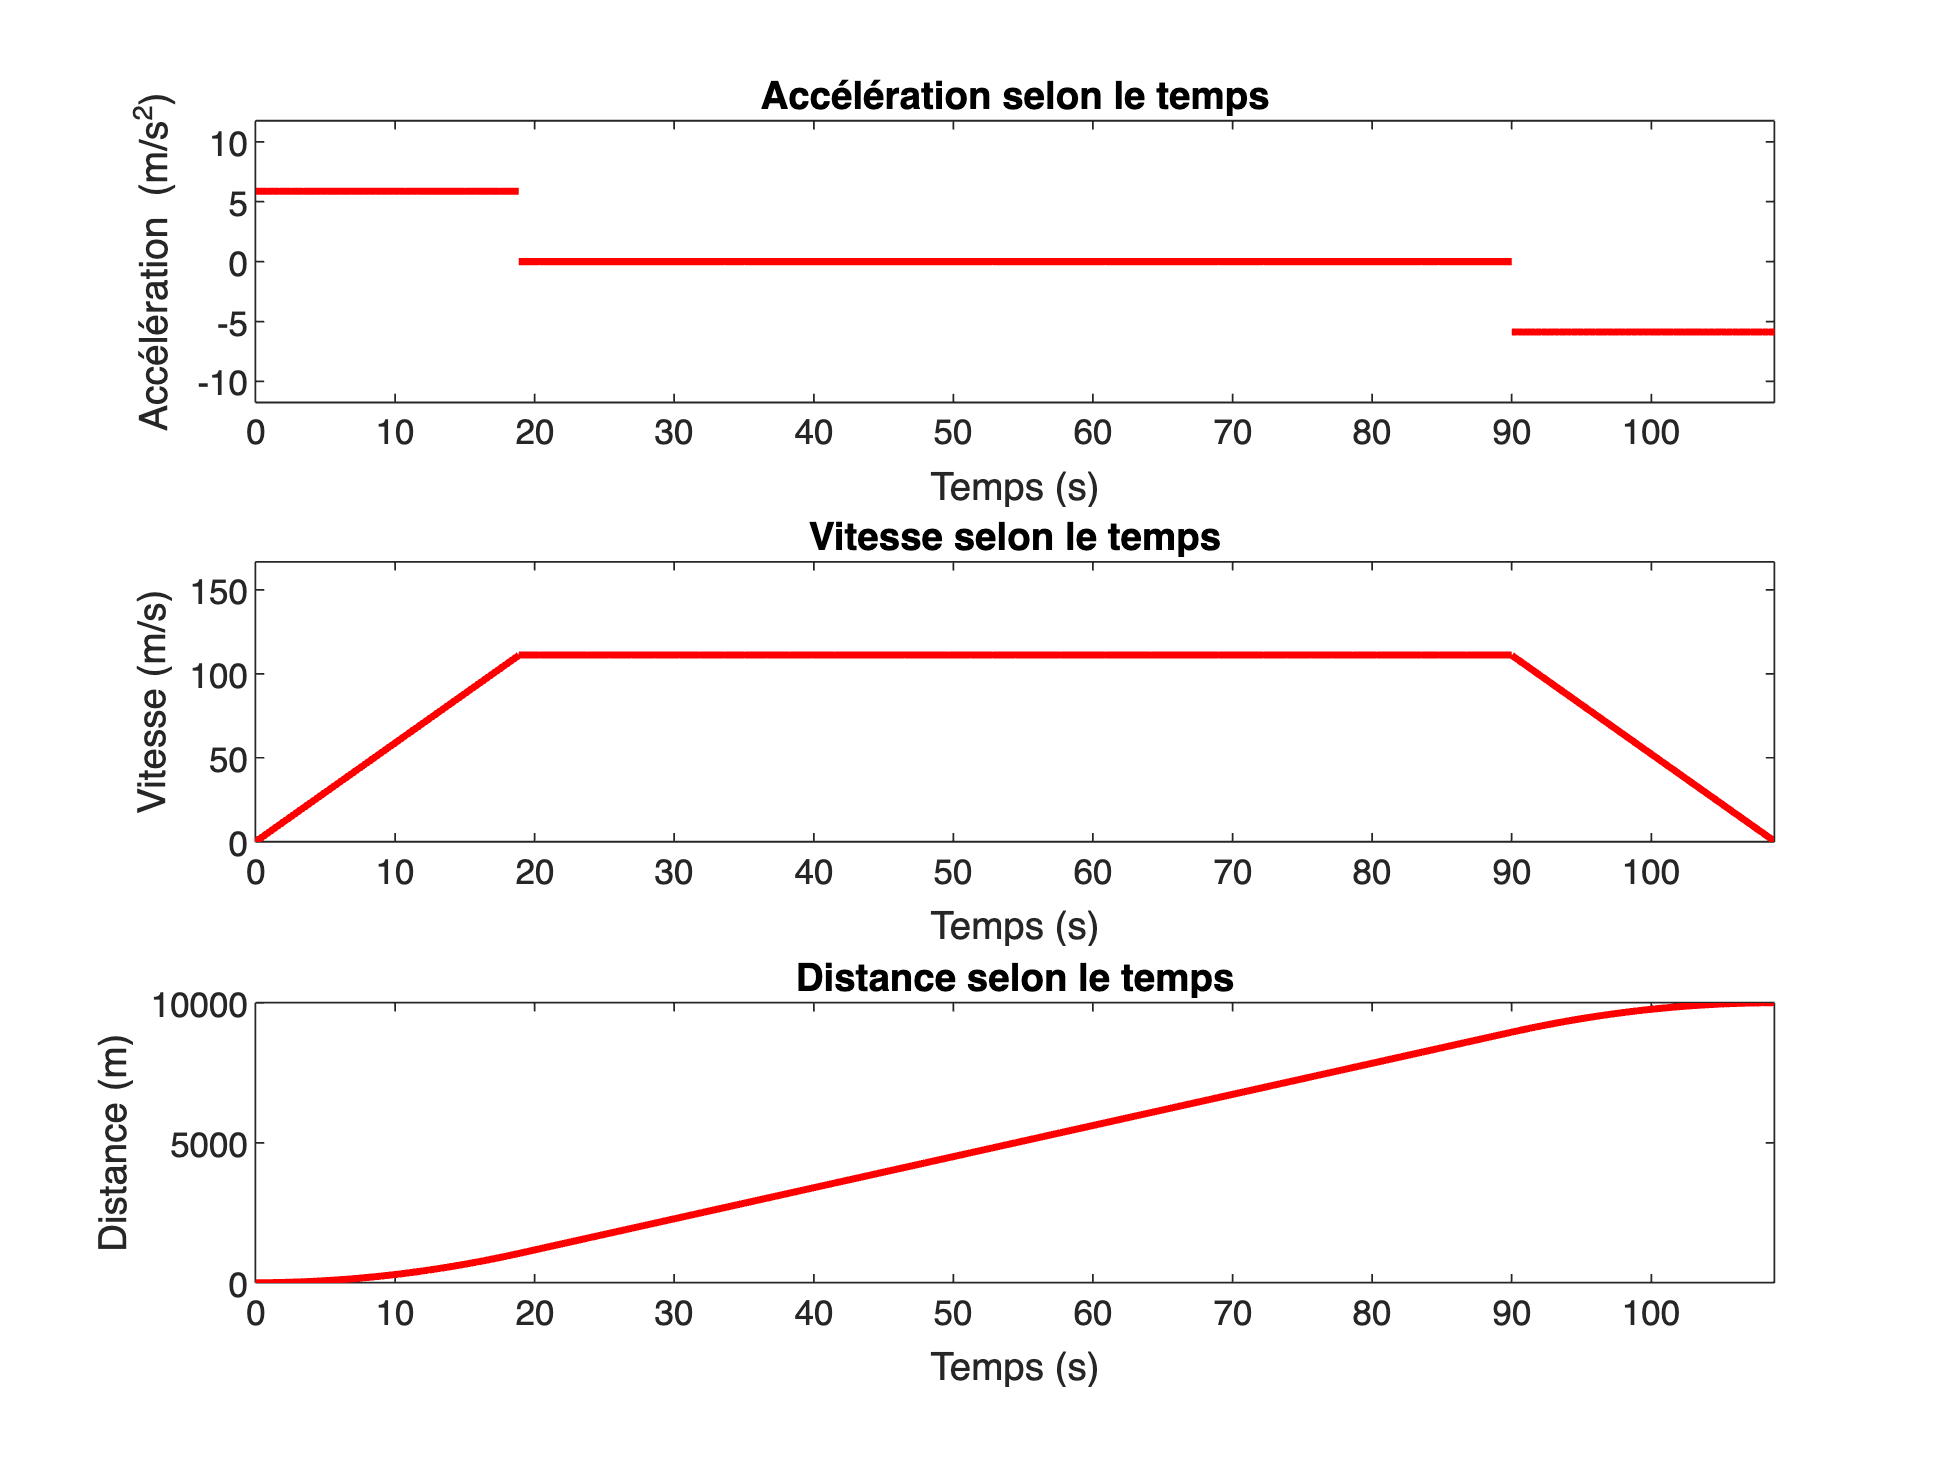

subplot(3, 1, 1);
fplot(A1, [t0 t1], 'linewidth', 2, 'color', "red");
hold on;
fplot(A2, [t1 t2], 'linewidth', 2, 'color', "red");
hold on;
fplot(A3, [t2 t3], 'linewidth', 2, 'color', "red");
ylim([(-Amax*2) (Amax*2)]);
title('Accélération selon le temps');
xlabel('Temps (s)');
ylabel('Accélération (m/s^2)');

subplot(3, 1, 2);
fplot(V1, [t0 t1], 'linewidth', 2, 'color', "red");
hold on; 
fplot(V2, [t1 t2], 'linewidth', 2, 'color', "red");
hold on;
fplot(V3, [t2 t3], 'linewidth', 2, 'color', "red");
ylim([(0) (Vmax * 1.5)]);
title('Vitesse selon le temps');
xlabel('Temps (s)');
ylabel('Vitesse (m/s)');

subplot(3, 1, 3);
fplot(D1, [t0 t1], 'linewidth', 2, 'color', "red");
hold on; 
fplot(D2, [t1 t2], 'linewidth', 2, 'color', "red");
hold on;
fplot(D3, [t2 t3], 'linewidth', 2, 'color', "red");
title('Distance selon le temps');
xlabel('Temps (s)');
ylabel('Distance (m)');

## Exercise 2: Déclaration de variables

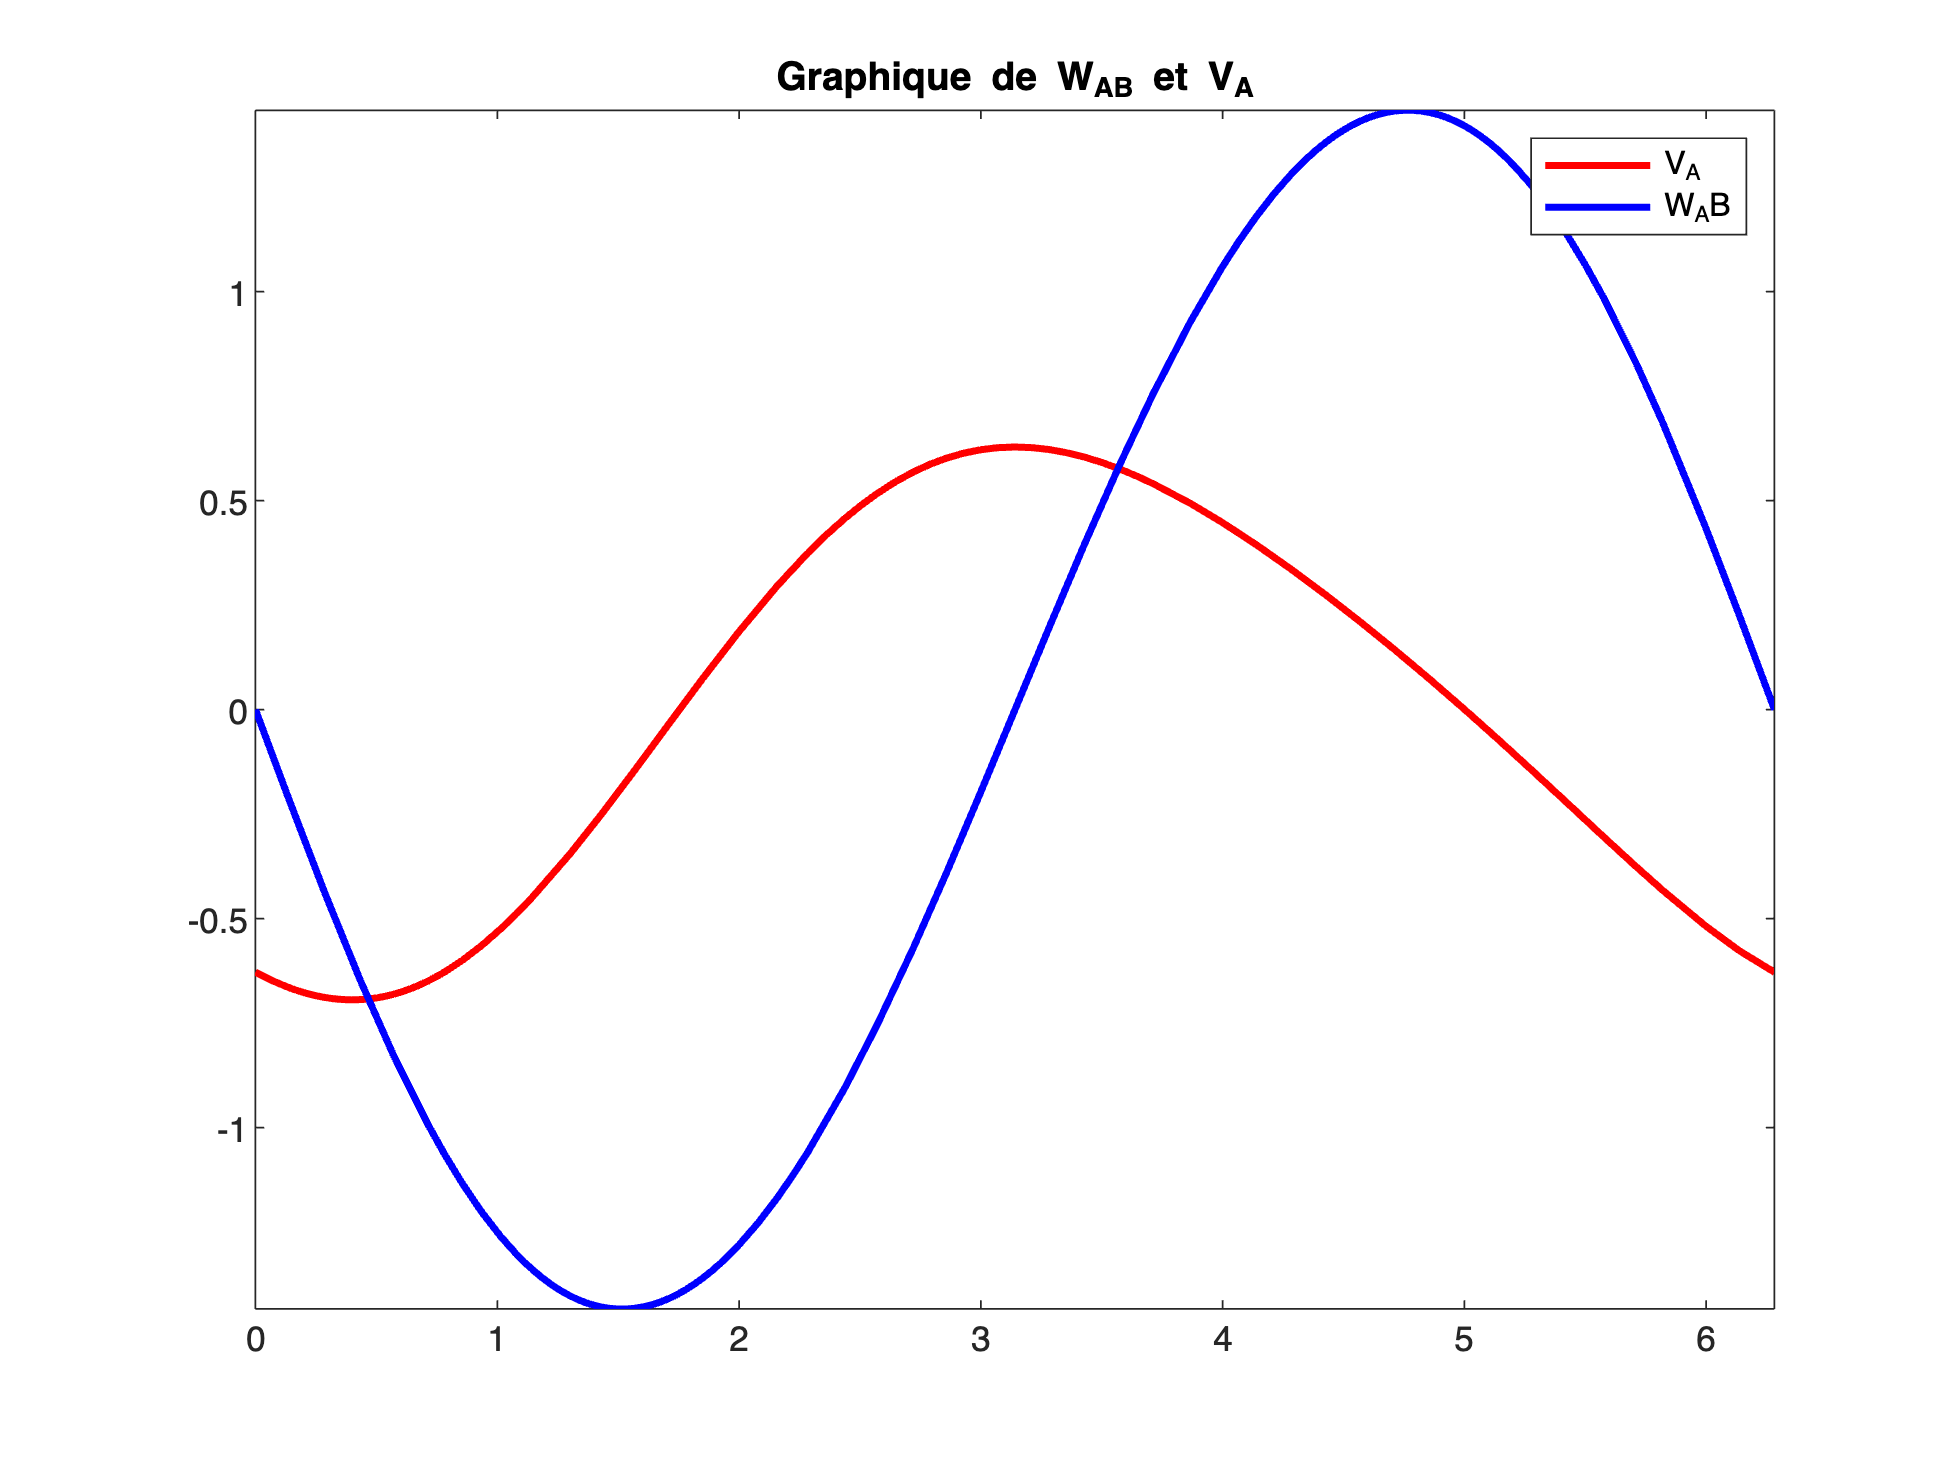

clc
clear
close all

syms teta
syms beta

OB = 0.1;
AB = 0.45;
Wob = 2*pi;

sB = (OB * (1 + cos(teta))) / AB;   %Sinus de Beta
cB = sqrt(1 - ((OB * (1 + cos(teta)))/AB).^2);    %Cos de Beta
Wab = (-OB/AB) * Wob * (sin(teta)/cB);

Va = (-OB * Wob * cos(teta)) + (AB * Wab * sB);

fplot(Va, [0 2*pi], 'LineWidth', 2, 'Color', "red")
hold on 
fplot(Wab, [0 2*pi], 'LineWidth', 2, 'Color', "blue")
hold on
legend('V_A', 'W_AB')
title('Graphique de W_A_B et V_A')

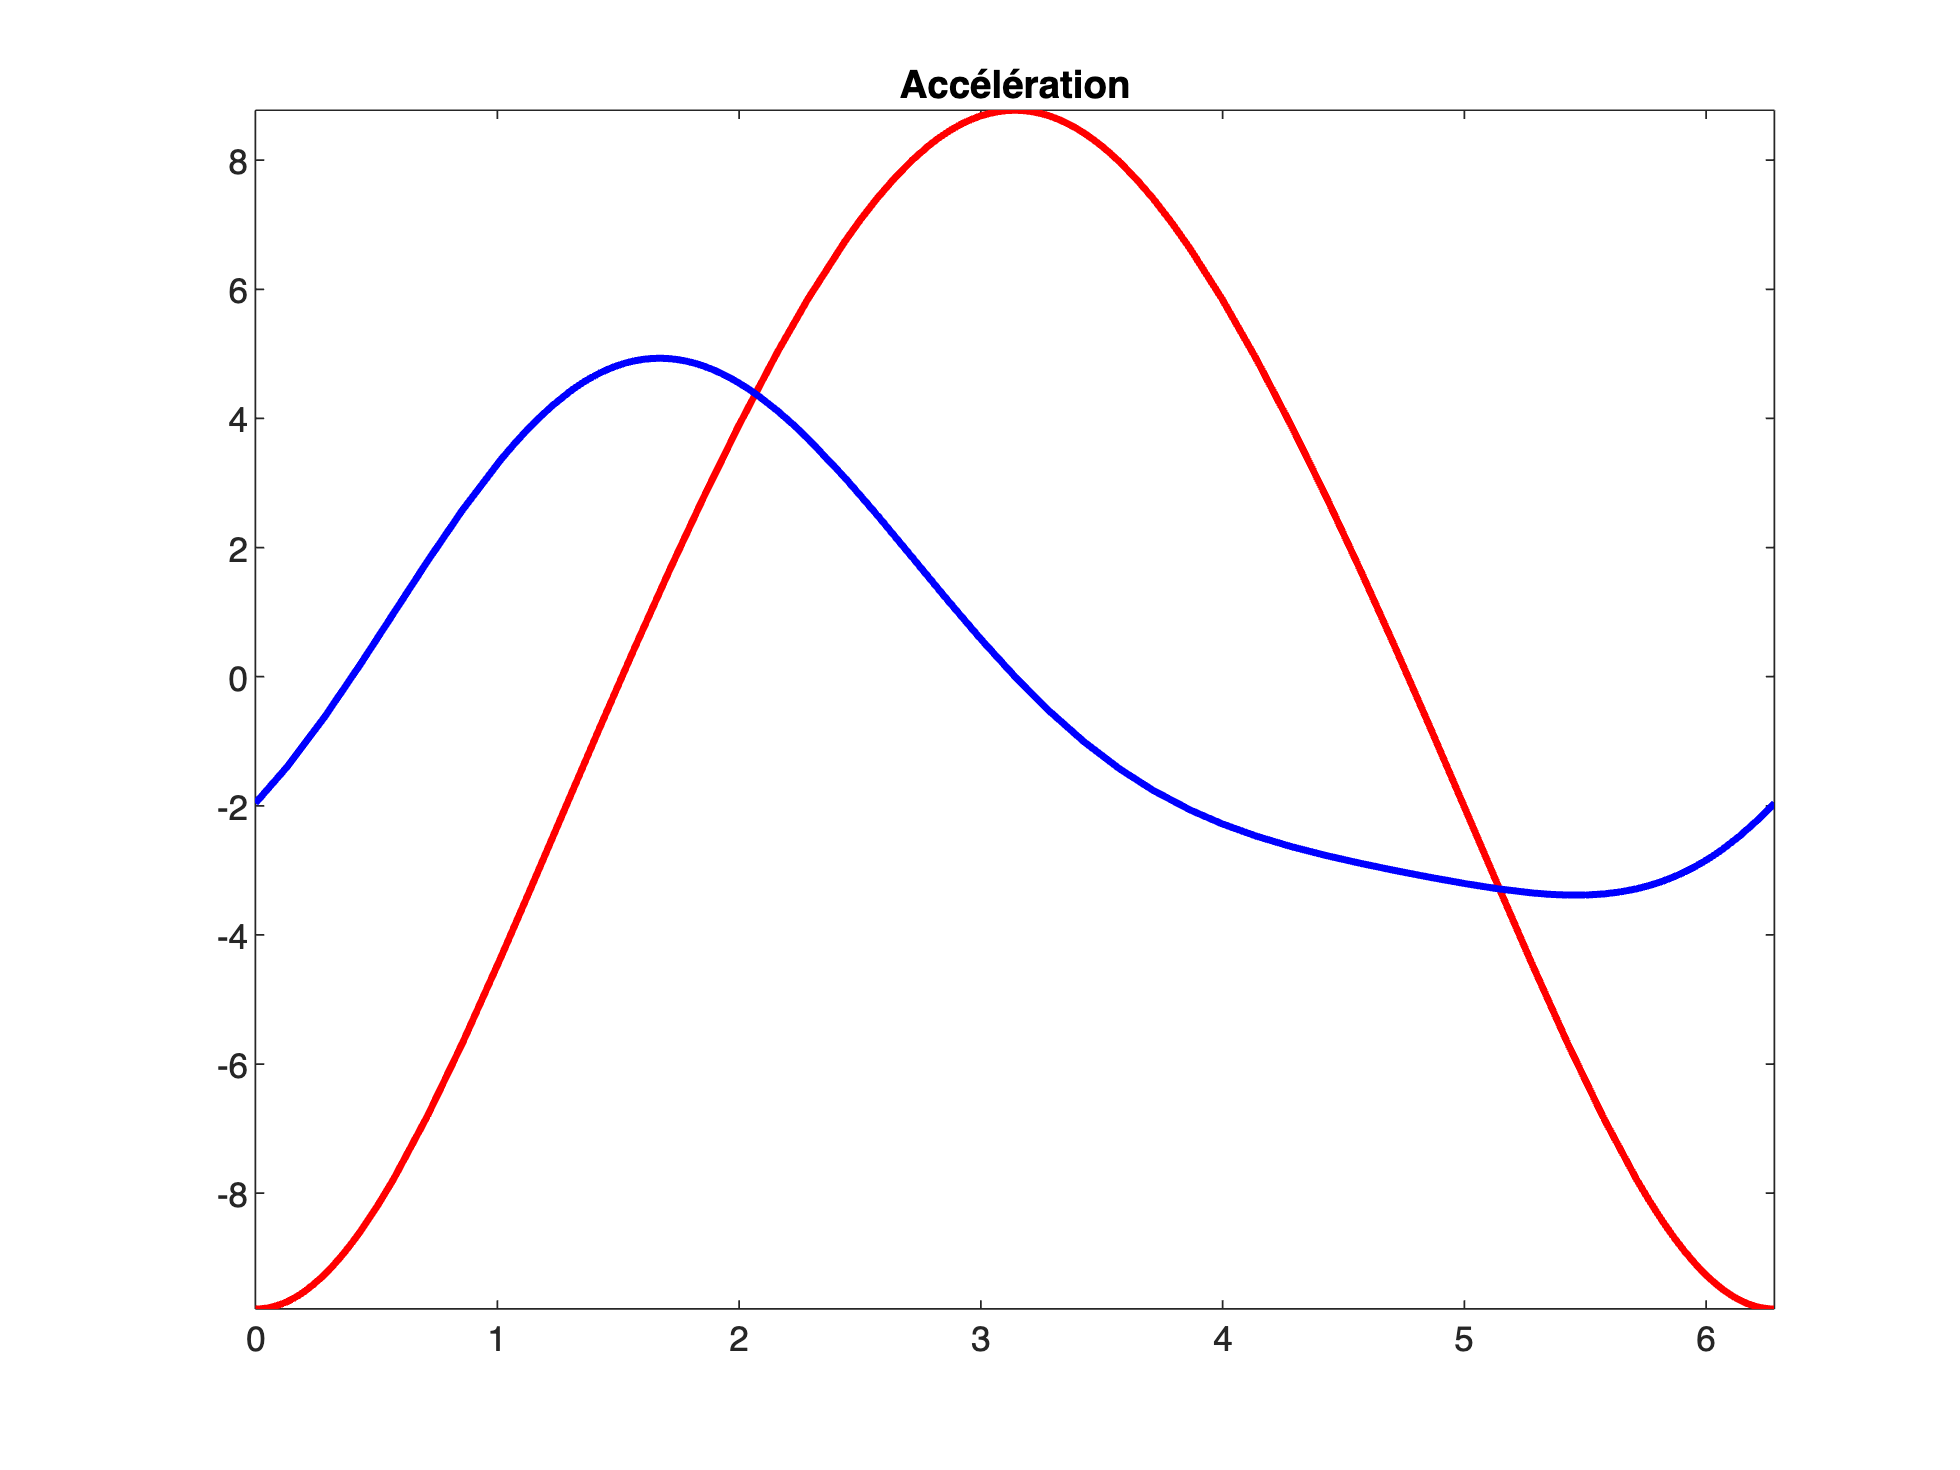

Aab = ((-OB * ((Wob).^2) * cos(teta)) + (AB * ((Wab).^2) * sB))/(AB * cB);
Aa = ((OB * ((Wob).^2)*sin(teta))+(AB*((Wab).^2)*cB)+(AB*Aab*sB));

figure;
fplot(Aab, [0 2*pi], 'LineWidth', 2, 'Color', "red")
hold on
fplot(Aa, [0 2*pi], 'LineWidth', 2, 'Color', "blue")
title('Accélération')